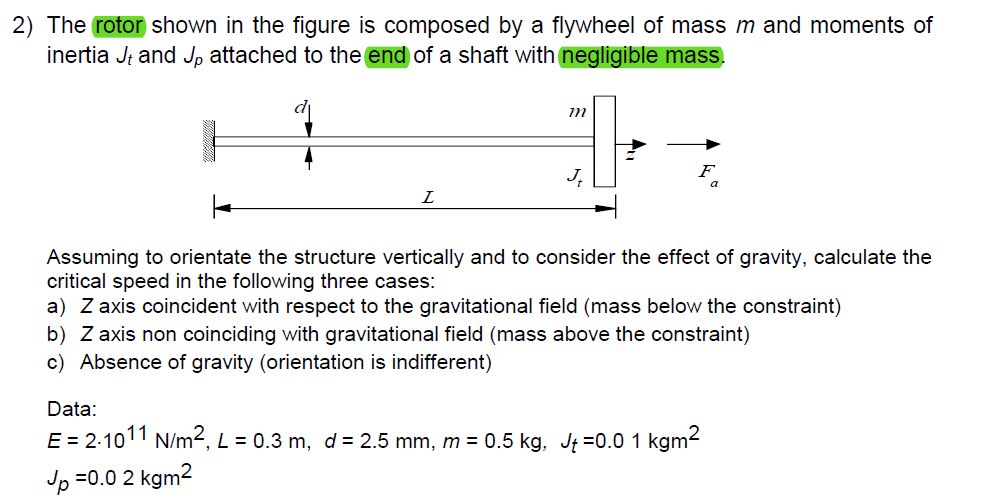

syms E v l Iy Jp m l w Fa

l=0.3

l = 0.3000

d=2.5e-03

d = 0.0025

m=0.5

m = 0.5000

Jt=0.01

Jt = 0.0100

E=2e11 

E = 2.0000e+11

ni=0.3

ni = 0.3000

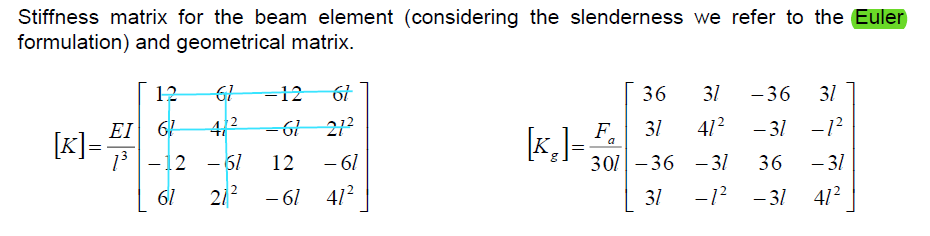

syms Fa
Fa=m*9.8

Fa = 4.9000

Iy=pi()*d^4/64;
Jp=0.02;

M=[m 0;0 Jt];
K=(E*Iy/l^3)*[12 -6*l;
             -6*l 4*l^2];
Kg=+Fa/(36*l)*[36 -3*l;
              -3*l 4*l^2];

eqn=det(-M*w^2+Kg)==0;

w_sol=solve(eqn);
% Fa_sol=solve(eqn,Fa)
% Fa_question=subs(Fa_sol,w,13.9)
% FAQ=double(Fa_question)

double(w_sol)

ans =     3.8076
    5.8738
   -3.8076
   -5.8738


w1=double(w_sol(1))

w1 = 3.8076

w2=double(w_sol(2))

w2 = 5.8738